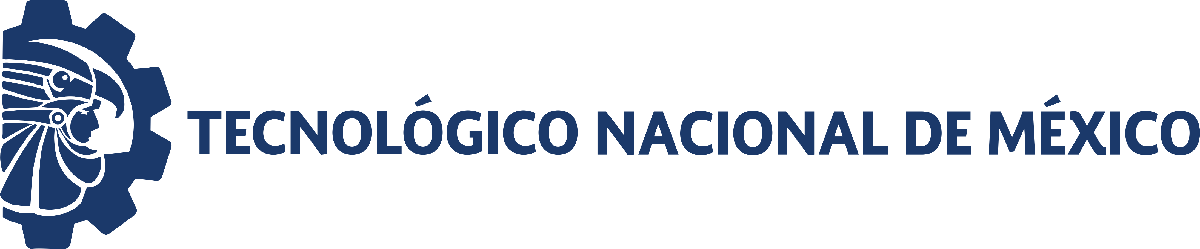                                 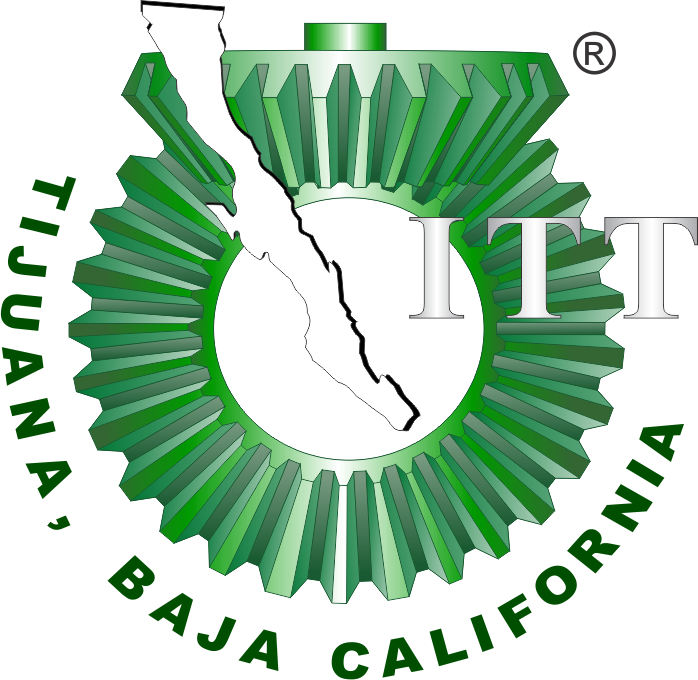

# Práctica 4: Mathematical modeling

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

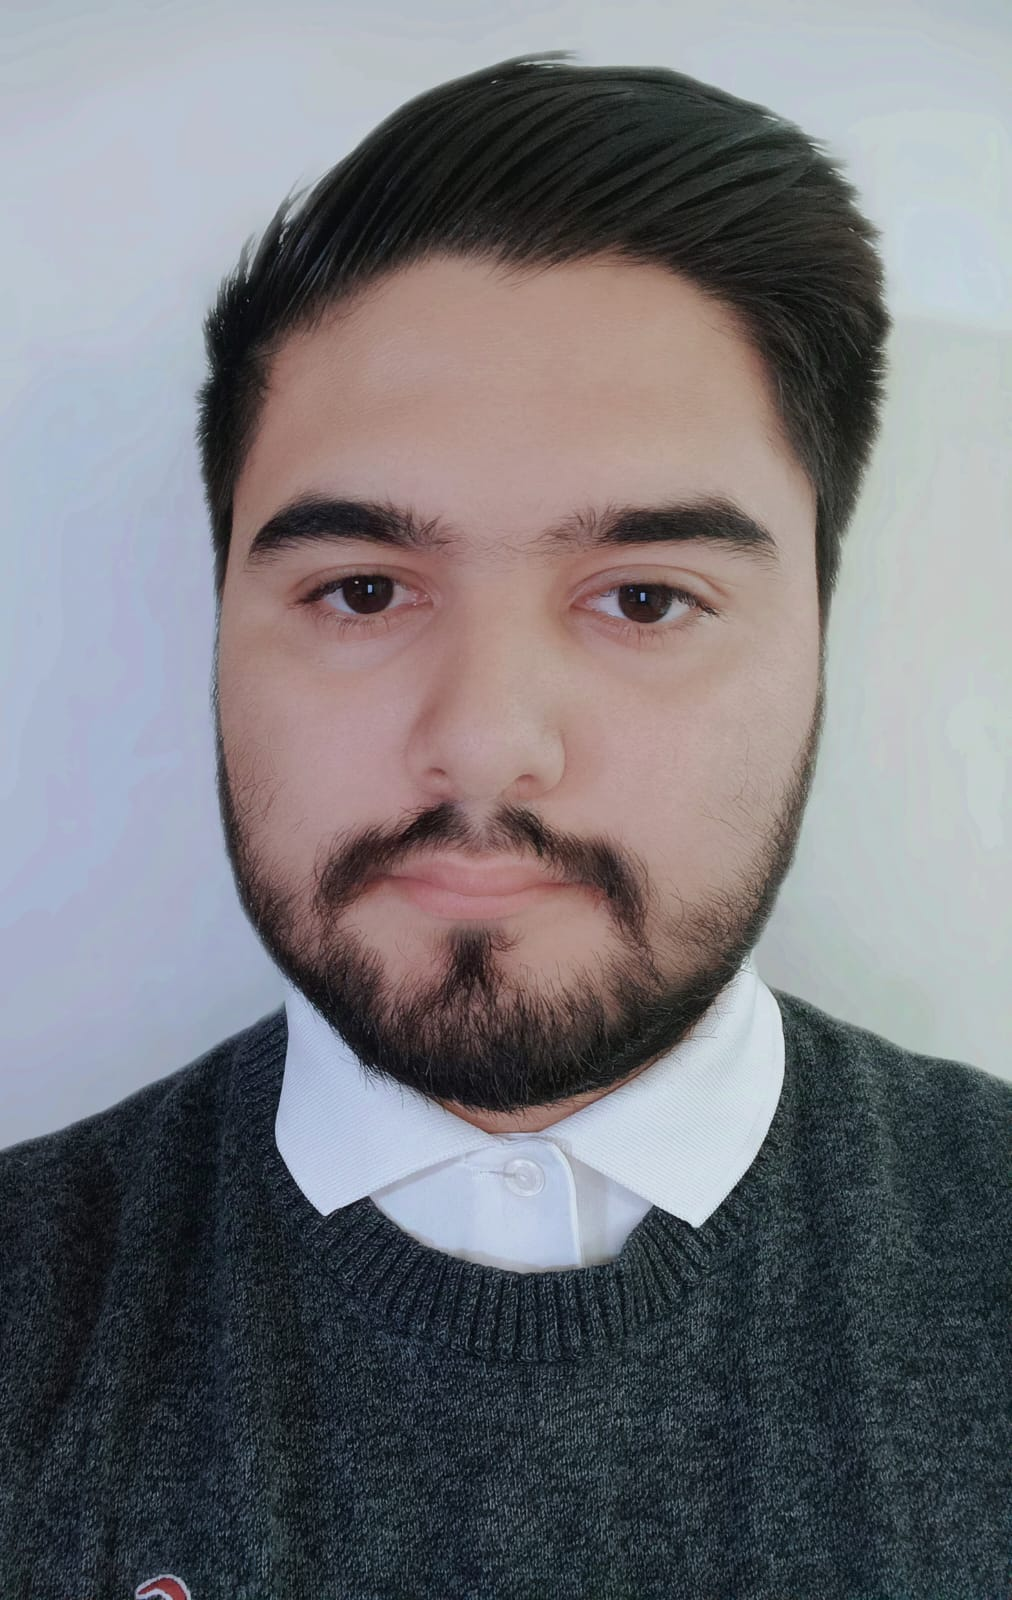

Nombre del alumno: **Jose Sebastian Delgado Soto**

Número de control: **C20212281**

Correo institucional: **l20212281@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## **Objetive**

Objective: Construct and analyze a mechanistic model of the dynamics between two biological variables.

## Simulation data

    Time     x(t)       y(t)  
    ____    _______    _______

      0     0.83086    0.99501
      5       1.662     2.5145
     10      2.2956     4.8358
     15       2.837     6.9758
     20      3.9255     6.9853
     25      3.9262     7.2348
     30      4.7409     6.7614
     35      4.5751     6.3823
     40      5.2588     6.3545
     45      5.1664     6.1724
     50      5.8318     6.0549
     55       6.006     4.8586
     60      5.8311     5.5353
     65      5.8493      5.113
     70      6.5819     5.3388
     75      6.8798     4.7416
     80      6.3799     4.5736
     85      6.8302     4.7893
     90      6.6908     4.1221
     95      7.1671     4.3096
    100      7.1736     4.6394
    105      6.6341      4.249
    110      7.3832      4.463
    115      7.5585     4.3067
    120      7.1246     4.1103
    125      7.5308     3.7325
    130      7.2664     4.118

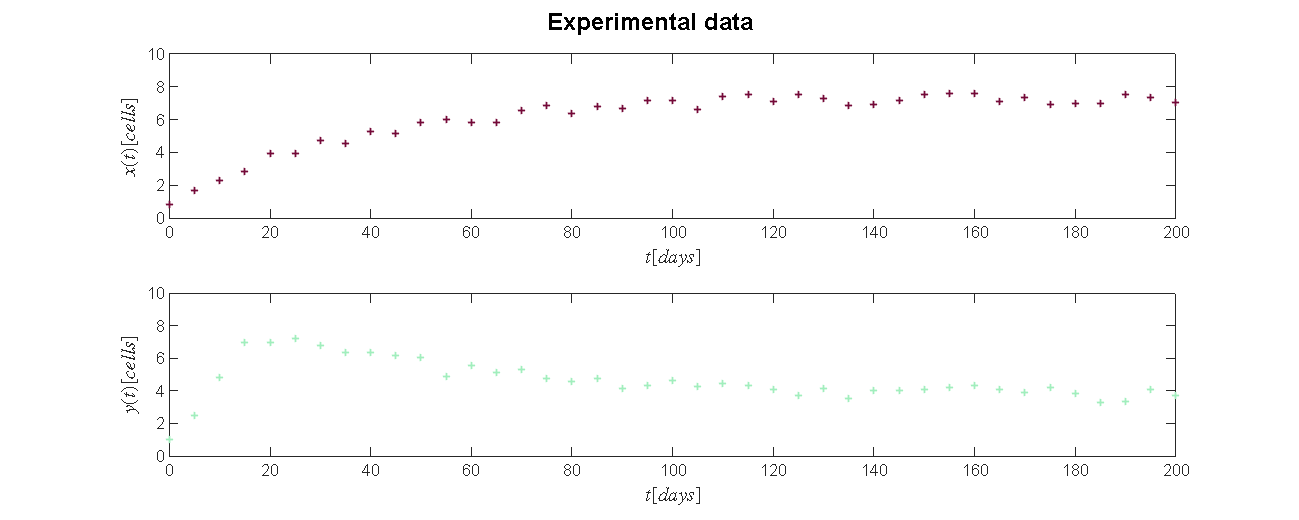

clc; clear; close all; warning('off','all')
filename = 'data.csv';
sys = readmatrix(filename);
to = sys(:,1);
xo = sys(:,2);
yo = sys(:,3);
rho1x = 0.5; gamma1 = 0.01;
rho2y = 0.001; gamma2 = 0.2;
P = [rho1x,gamma1,rho2y,gamma2];
T = array2table([to, xo, yo], 'VariableNames', {'Time', 'x(t)', 'y(t)'});

disp(T); plotdata(to,xo,yo)

    Parameters    Estimate       SE          MoE              CI95             pvalue  
    __________    ________    _________    ________    __________________    __________

      rho1        0.15265     0.0053858    0.010722    0.14193    0.16337    8.0468e-43
      gamma1      0.67149      0.012893    0.025668    0.64582    0.69716    2.3469e-62
      rho2        0.27411      0.011136     0.02217    0.25194    0.29628    1.6093e-38
      gamma2      0.82706     0.0083655    0.016654    0.81041    0.84371     9.992e-84



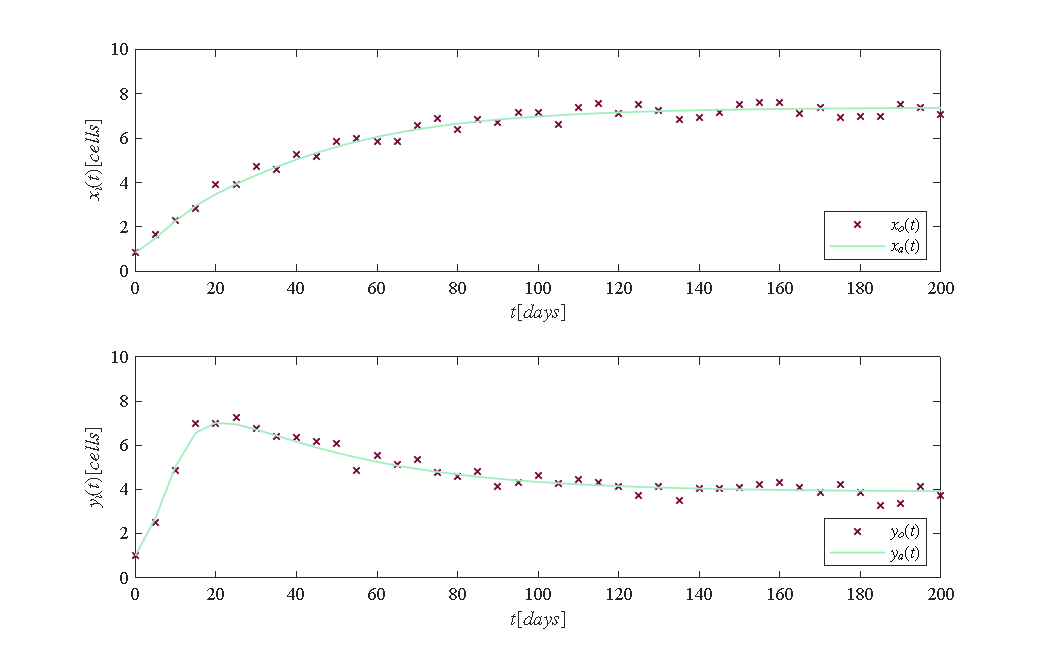

P0 = [0.1; 0.1; 0.1; 0.1];
[mdl, xa, ya] = variant(to,xo,yo,P0); plotResults(to, [xo,xa], [yo,ya])

## Equilibrium points and Jacobian matrix

clc; clear; close all; warning('off','all')
syms x y rho1 rho2 gamma1 gamma2 beta
dx = rho1*x*(1 - (x + gamma1*y)/beta);
dy = rho2*y*(1 - (y + gamma2*x)/beta);
J = jacobian([dx,dy],[x,y]);
fprintf('Jacobian matrix of the Lotka-Volterra system:'); disp(J)

Jacobian matrix of the Lotka-Volterra system:

$$\left(\begin{array}{cc} -\rho_{1}\,\left(\frac{x+\gamma_{1}\,y}{\beta }-1\right)-\frac{\rho_{1}\,x}{\beta } & -\frac{\gamma_{1}\,\rho_{1}\,x}{\beta }\\ -\frac{\gamma_{2}\,\rho_{2}\,y}{\beta } & -\rho_{2}\,\left(\frac{y+\gamma_{2}\,x}{\beta }-1\right)-\frac{\rho_{2}\,y}{\beta } \end{array}\right)$$


dx = rho1*x*(1 - (x + gamma1*y)/beta) == 0;
dy = rho2*y*(1 - (y + gamma2*x)/beta) == 0;
edos = solve([dx,dy],[x,y]);
fprintf(['The Lotka-Volterra system has ', num2str(length(edos.x)), ' equilibrium points.']);

The Lotka-Volterra system has 4 equilibrium points.

X0 = edos.x(1); Y0 = edos.y(1);
X1 = edos.x(2); Y1 = edos.y(2);
X2 = edos.x(3); Y2 = edos.y(3);
X3 = edos.x(4); Y3 = edos.y(4);
syms x0 y0 x1 y1 x2 y2 x3 y3
fprintf('Equilibrium points of the Lotka-Volterra system:'); disp([x0,y0,X0,Y0]); disp([x1,y1,X1,Y1]); disp([x2,y2,X2,Y2]); disp([x3,y3,X3,Y3]);

Equilibrium points of the Lotka-Volterra system:

$$\left(\begin{array}{cccc} x_{0} & y_{0} & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{1} & y_{1} & \beta & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{2} & y_{2} & 0 & \beta \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{3} & y_{3} & \frac{\beta \,\left(\gamma_{1}-1\right)}{\gamma_{1}\,\gamma_{2}-1} & \frac{\beta \,\left(\gamma_{2}-1\right)}{\gamma_{1}\,\gamma_{2}-1} \end{array}\right)$$

clear gamma1 gamma2 beta
gamma1 = 0.67149; gamma2 = 0.82706;
beta = 10;
disp('(x0,y0) = (0,0)'); disp(['(x1,y1) = (', num2str(beta),',',num2str(0),')']); disp(['(x2,y2) = (', num2str(0),',',num2str(beta),')']); disp(['(x3,y3) = (', num2str(beta * (gamma1 - 1) / (gamma1 * gamma2 - 1)),',',num2str(beta * (gamma2 - 1) / (gamma1 * gamma2 - 1)),')'])

(x0,y0) = (0,0)
(x1,y1) = (10,0)
(x2,y2) = (0,10)
(x3,y3) = (7.3883,3.8895)


## Local stability

clc; clear; close all; warning('off','all')
gamma1 = 0.67149; gamma2 = 0.82706;
rho1 = 0.15265; rho2 = 0.27411;
beta = 10;
syms x y
dx = rho1*x*(1 - (x + gamma1*y)/beta) == 0;
dy = rho2*y*(1 - (y + gamma2*x)/beta) == 0;
edos = solve([dx,dy],[x,y]);
x0 = double(edos.x(1)); y0 = double(edos.y(1));
x1 = double(edos.x(2)); y1 = double(edos.y(2));
x2 = double(edos.x(3)); y2 = double(edos.y(3));
x3 = double(edos.x(4)); y3 = double(edos.y(4));
clear x y
x = [x0;x1;x2;x3]; y = [y0;y1;y2;y3];
var = {'(x0,y0)';'(x1,y1)';'(x2,y2)';'(x3,y3)'};
Equilibria = table(x,y,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye'};
fprintf('Equilibrium points of the Lotka-Volterra system:\n'); disp(Equilibria)

Equilibrium points of the Lotka-Volterra system:
                 xe        ye  
               ______    ______

    (x0,y0)         0         0
    (x1,y1)        10         0
    (x2,y2)         0        10
    (x3,y3)    7.3883    3.8895



L = zeros(length(x),2);
for i = 1:length(x)
     J = [-rho1 * ((x(i) + gamma1 * y(i)) / beta - 1) - rho1 * x(i) / beta, -rho1 * x(i) * gamma1 / beta;
         -rho2 * y(i) * gamma2 / beta, -rho2 * ((y(i) + gamma2 * x(i)) / beta - 1) - rho2 * y(i) / beta]
     L(i,:) = eig(J);
end

J =     0.1527         0
         0    0.2741


J =    -0.1527   -0.1025
         0    0.0474


J =     0.0501         0
   -0.2267   -0.2741


J =    -0.1128   -0.0757
   -0.0882   -0.1066


L1 = L(:,1); L2 = L(:,2);
Lambdas = table(L1,L2,'RowNames',var);
disp('Eigen values of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas)

Eigen values of the Jacobian matrix evaluated at each equilibrium point:
                  L1          L2    
               ________    _________

    (x0,y0)     0.15265      0.27411
    (x1,y1)    -0.15265     0.047405
    (x2,y2)    -0.27411     0.050147
    (x3,y3)    -0.19147    -0.027922



Con base al análisis matemático, se determina que:

- Si 𝜆₁ y 𝜆₂ son reales y positivos, el sistema es inestable (trayectorias se alejan del equilibrio).

- Si 𝜆₁ y 𝜆₂  son reales y de signos opuestos, el sistema también es inestable (al menos uno es positivo).

- Si ambos son reales y negativos, el sistema es localmente asintóticamente estable.

## Equilibrium points

    Parameters    Estimate       SE          MoE              CI95             pvalue  
    __________    ________    _________    ________    __________________    __________

      rho1        0.15265     0.0053857    0.010722    0.14193    0.16337    8.0375e-43
      gamma1      0.67149      0.012893    0.025668    0.64582    0.69716    2.3469e-62
      rho2        0.27411      0.011136    0.022169    0.25194    0.29628    1.6066e-38
      gamma2      0.82706     0.0083655    0.016654    0.81041    0.84371    9.9926e-84



clc; clear; close all; warning('off','all')
sys = readmatrix('data.csv');
to = sys(:,1);
xo = sys(:,2);
yo = sys(:,3);
gamma1 = 0.67149; gamma2 = 0.82706;
rho1 = 0.15265; rho2 = 0.27411;
P0 = [rho1,gamma1,rho2,gamma2];
[mdl, xa, ya] = variant(to,xo,yo,P0); plotResults(to, [xo,xa], [yo,ya])

## Functions:

### Plot data:

function plotdata(to, xo, yo)
c1=[116, 9, 56]/255;  
c2=[161, 238, 189]/255;  


    set(figure(), 'Color', 'w')
    FS = 11;
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,25,10])
    
  %primera grafica
    subplot(2,1,1)
    plot(to, xo, '+', 'LineWidth', 1, 'MarkerSize', 4, 'Color', c1)
    hold on
    xlabel('$t [days]$', 'Interpreter', 'Latex', 'fontsize', FS)
    ylabel('$x(t) [cells]$', 'Interpreter', 'Latex', 'fontsize', FS)
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)
%segunda grafica
    subplot(2,1,2)
    plot(to, yo, '+', 'LineWidth', 1, 'MarkerSize', 4, 'Color', c2)
    hold on
    xlabel('$t [days]$', 'Interpreter', 'Latex', 'fontsize', FS)
    ylabel('$y(t) [cells]$', 'Interpreter', 'Latex', 'fontsize', FS)
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)
    
    sgtitle('Experimental data', 'FontSize', FS + 2, 'FontWeight', 'bold');
    
    saveas(gcf, 'Experimental Data.png')
end


## MDL

function [mdl, xa, ya] = variant(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1); 
    fo = [xo;yo]; to = [to;to]; 
    beta = 10;

    function fi = model(p, t)
        rho1 = p(1); gamma1 = p(2); rho2 = p(3); gamma2 = p(4);
        dt = 1E-2;
        t = reshape(t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = x0;
        y = zeros(length(time),1); y(1) = y0;

        for i = 1:n
            [fx, fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn, fyn] = f(xn, yn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end

        function [dx, dy] = f(x, y)
            dx = rho1*x*(1 - (x + gamma1*y)/beta);
            dy = rho2*y*(1 - (y + gamma2*x)/beta);
        end

        xi = zeros(length(t),1);  
        yi = zeros(length(t),1);
        
        for i = 1:length(t)
            k = abs(time - t(i)) < 1E-9; 
            xi(i) = x(k);
            yi(i) = y(k);
        end

        fi = [xi;yi];
    end

    mdl = fitnlm(to,fo,@model,P0); 
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE; 
    tval = tinv(1 - alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['rho1  ';'gamma1';'rho2  ';'gamma2'];
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);
    disp(Results)

    fa = mdl.Fitted;
    fx = reshape(fa,[],2);
    xa = fx(:,1);
    ya = fx(:,2);
end

##  PLOT RESULTS

function plotResults(to, xo, yo)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12.5]);

   colores = [116, 9, 56;
           161, 238, 189;
           170, 84, 134;
           255, 101, 0;
           123, 211, 234;
           181, 159, 120;
            42,  54,  99;
            26,  26,  29;
            254, 236, 55;
            165, 182, 141;

                 ]/255;
colororder(colores)
    hold on; box on; grid off; 

    subplot(2,1,1)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(to, xo(:,1), 'x', 'MarkerSize', 5, 'LineWidth', 1);
    plot(to, xo(:,2), '-', 'LineWidth', 1);
    xlabel('$t [days]$', 'Interpreter', 'Latex');
    ylabel('$x_i(t) [cells]$', 'Interpreter', 'Latex');
    xlim([0 200]); xticks(0:20:200);
    ylim([0 10]); yticks(0:2:10);
    L = legend('$x_o(t)$', '$x_a(t)$');
    set(L, 'Interpreter', 'Latex','Location', 'SouthEast');

    subplot(2,1,2)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(to, yo(:,1), 'x', 'MarkerSize', 5, 'LineWidth', 1);
    plot(to, yo(:,2), '-', 'LineWidth', 1);
    xlabel('$t [days]$', 'Interpreter', 'Latex');
    ylabel('$y_i(t) [cells]$', 'Interpreter', 'Latex');
    xlim([0 200]); xticks(0:20:200);
    ylim([0 10]); yticks(0:2:10);
    L = legend('$y_o(t)$', '$y_a(t)$');
    set(L, 'Interpreter', 'Latex','Location', 'SouthEast');
end